# Project 1: Numerical ODEs

NAMES HERE

## Problem 1


$$\frac{\textrm{dy}}{\textrm{dt}}=-2{\;t\;y}^2 ,y\left(0\right)=1$$


**(a)**

One can solve the above IVP using separation of variables, since the equation is separable. This can be seen by setting $p(t) = -2t$ and $q(y) = y^2$. It then takes on the form $dy/dt = p(t)q(y)$ and we can solve it using separation of variables. First we can rewrite it as


$$\frac{\textrm{dy}}{y^2 }=-2t\;\textrm{dt}$$


and integrating both sides with respect to the corresponding variable ($y$ or $t$) yields 

$-\frac{1}{y}=-\frac{2t^2 }{2}+C$. 

Solving the equation for $y$ thus yields 

$y=\frac{1}{t^2 +c}$. 

This is the general solution for the IVP, where $c$ is an arbituary constant dependent on the initial value. Plugging in $y(0) = 1$, we find that $c = -1$ and therefore


$$y=\frac{1}{t^2 +1}$$


is the solution to the IVP. 

**(b)**

Euler's method is a numerical approximation that uses discrete points to approximate a continuous curve. It is useful when we have a differential equation that we cannot solve exactly and must approximate the solution. It takes on the form

$\hat{y} {\;}_{n+1} =\hat{y} {\;}_n +h*f\left(t_n ,\hat{y} {\;}_n \right)$, 

where $\hat{y}_{n}$ and $\hat{y}_{n+1}$ are the approximations of the $y$ values for grid points $n$ and $n+1$ respectfully, $h$ is the spacing between grid points, and $f$ is the derivative with respect to independent variable $t$ of a function $y$. Specifically for the purposes of this problem, the Euler approximation is 

$\hat{y} {\;}_{n+1} =\hat{y} {\;}_n +h*\left(-2{t_n {\hat{y} }_n }^2 \right)$.

Therefore,

$\hat{y} {\;}_{n+1} =\hat{y} {\;}_n -2\;{h\;t}_n \hat{y} {\;}_n^2$. 

**(c)**

[Typeset Mathematical Work Here]

**(d)**

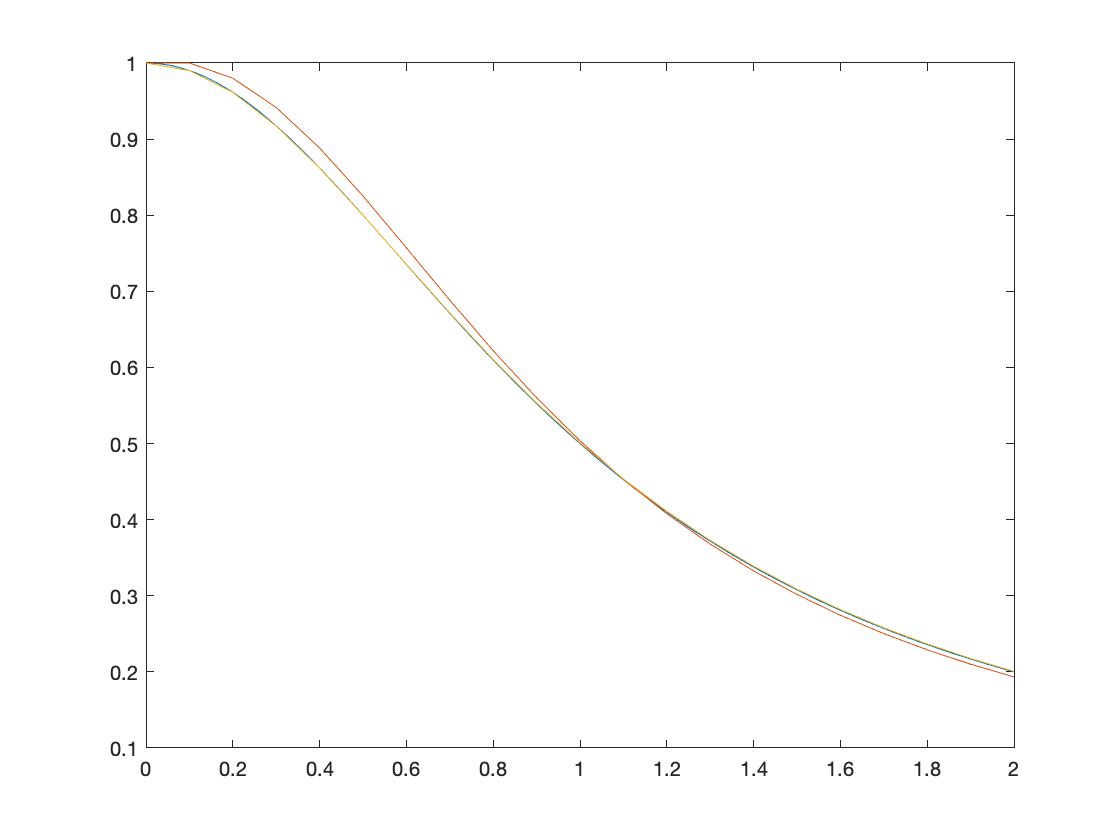

% code goes here
f = @(t, y) -2.*t.*y.^2;
soln1 = @(t) 1./(t.^2 + 1); 
t = linspace(0,2) ;
h = 0.1;

[t_arr, y_arr] = myEuler(1, 0, f, 2/h, h); 
[t_arr_imp, y_arr_imp] = myImprovedEuler(1, f, 2/h, h);


figure
plot(t, soln1(t))
hold on
plot(t_arr, y_arr)
plot(t_arr_imp, y_arr_imp)

**(e) **(f) calculating the error: $E_n =\max \left|\;y\left(t_n \right)\;\;-y_n \right|$

% code goes here 

[Discussion goes here]

**(f)**

 Rate of convergence found using $p\approx \log_2 \left(\frac{E_n \left(h\right)}{E_{2n} \left(\frac{h}{2}\right)}\right)$

% code goes here 

**(g)**

% code goes here 


**(h)**

[Typeset summary paragraph here]

## Problem 2


$$\frac{\textrm{dy}}{\textrm{dt}}=\frac{3t^2 }{3y^2 -2},y\left(0\right)=0$$


**(a)**

[Typeset Mathematical Work Here]

**(b)**

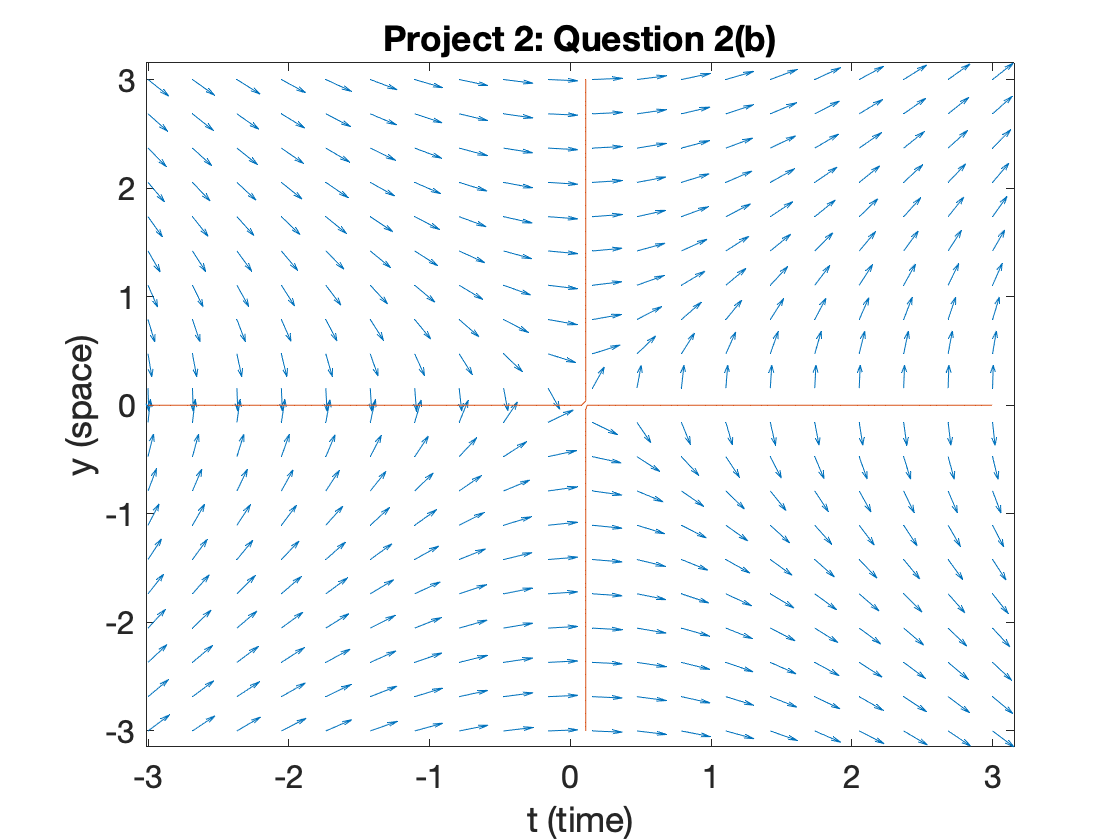

% code goes here
clear all % clear all variables in the workspace
set(0, 'DefaultAxesFontSize', 16) % increase font size in our figure

% define rate function using componentwise arithmetic
f = @(y,t) (3.*t.*exp(2))./(3.*y.*exp(2)-2);

% define grid for direction field
[T,Y] = meshgrid(linspace(-3,3,20),linspace(-3,3,20));

% if you want to see what meshgrid is doing
%figure;
%plot(T,P,'o')

% calculate slope (p'(t)) at each point in our grid
F = f(Y, T);

% normalize arrows to length 1
L = sqrt(1 + F.^2);

% At each point (T,P), draw the unit vector (1/L,F/L) and scale by 0.5
figure;
quiver(T, Y, 1./L, F./L,0.5)
hold on

fimplicit(f,[-3 3 -3 3])

% label axes
axis tight
xlabel('t (time)')
ylabel('y (space)')
title('Project 2: Question 2(b)')

**(c)**

[Typeset Mathematical Work Here]

**(d)**

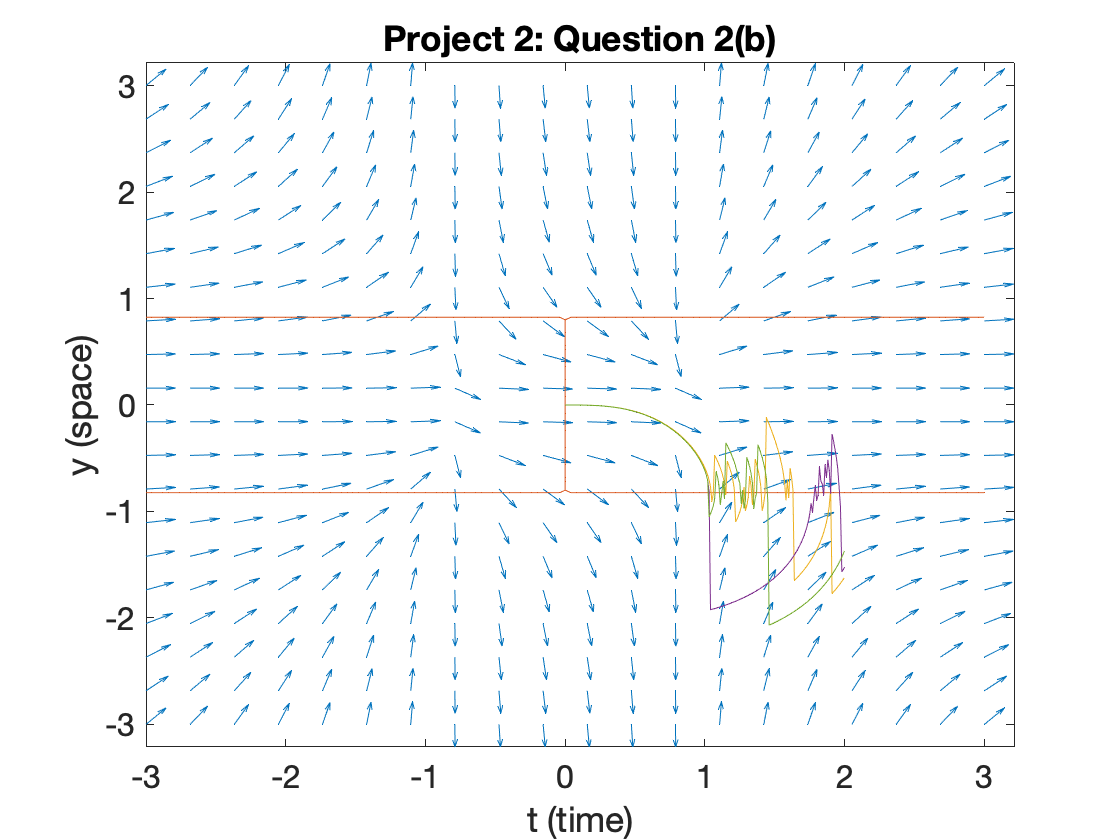

% code goes here
clear all % clear all variables in the workspace
set(0, 'DefaultAxesFontSize', 16) % increase font size in our figure

% define rate function using componentwise arithmetic
f = @(t,y) (3.*t.^2)./(3.*y.^2-2);

% define grid for direction field
[T,Y] = meshgrid(linspace(-3,3,20),linspace(-3,3,20));

% if you want to see what meshgrid is doing
%figure;
%plot(T,P,'o')

% calculate slope (p'(t)) at each point in our grid
F = f(Y, T);

% normalize arrows to length 1
L = sqrt(1 + F.^2);

t = linspace(0,2) ;
h = 0.01;
[t_arr, y_arr] = myEuler(0, 0, f, 2/h, h);
[t_arr_imp, y_arr_imp] = myImprovedEuler(0, f, 2/h, h);
[t_arr_rk, y_arr_rk] = myRK4(0, f, 2/h, h);

% At each point (T,P), draw the unit vector (1/L,F/L) and scale by 0.5
figure;
quiver(T, Y, 1./L, F./L,0.5)
hold on

fimplicit(f,[-3 3 -3 3])
plot(t_arr, y_arr)
plot(t_arr_imp, y_arr_imp)
plot(t_arr_rk, y_arr_rk)

% label axes
axis tight
xlabel('t (time)')
ylabel('y (space)')
title('Project 2: Question 2(b)')

**(e)**

[Typeset Discussion Here]

**(f)**

Now for $y\left(0\right)=1$. 

% code goes here 


**(g)**

[Typset summary paragraph here]

## Problem 3

**(a)**

[Typeset Mathematical Work Here]

**(b)**

[Typeset Mathematical Work Here]

**(c)**

% code goes here


**(d)**

[Typeset Discussion Here]

## Problem 4

Climate change is becoming an increasingly important concern in our world right now, as the increase in global temperatures could have long-term, irreversible effects on our weather patterns and temperatures. Although fluctations in temeprature are natural, human activities like burning fossil fuels have caused for an overabundance of greenhouse gases in the atmosphere that can lead to disasterous effects on our global climate. It is important to model these changes in temperature to understand how the temperature changes as a function of the current temperature and efforts of the government to regulate emissions. 

Many experts predict that an increase in $2^o$C increase in temperature will cause the global temperature to depart from a current state of equilibrium and cause a positive feedback loop that results in a new equilibirum $6^{o}$ C higher than the current equilibrium. This would be a significant change and be disastrous for the species and climates on Earth. 

To model this, we have developed a differential equation that demonstrates the relationship between the rate of temperature change $dT/dt$, the current temperature $T$, and the impact of government regulation on the temperature $k$.  This variables have been found by experts to have the relationship

$\frac{\textrm{dT}}{\textrm{dt}}=-\frac{1}{10}\left(T-20\right)\left(T-22\right)\left(T-26\right)-k$,

where the $-1/10$ prefactor is a proportionality constant between the temperature and the rate of temperature change. The $k$ is subtracted from the temperature term based on the assumption that an increase in government regulation decreases the rate of temperature change. In other words, an increase in regulation should work to reverse an increase in temperature. In this form, one can also easily see the equilibrium solutions. It is assumed that the current equilibirum is at $T = 20^{o}$ C, but a $2^{o}$ temperature change will begin a positive feedback loop such that there is a new equilibrium temperature at $26^{o}$ C. At these points the rate of temperature change is constant unless there is an impact due to government regulations.

**(i) Baseline Figure**

% code goes here

[Typeset Summary Paragraph Here]

**(ii) Increased Regulation Figure**

% code goes here

[Typeset Summary Paragraph Here]

**(i) Decreased Regulation Figure**

% code goes here

[Typeset Summary Paragraph Here]

**"How do you know that your approximated solutions are even accurate?"**

[Typeset ResponseHere]

## Honor Code

I have neither given or recieved unauthorized aid on this assignment.  

[Upload an image of your signature here]